%% Human Activity Recognition using 1D-CNN
% Author: Bhogala Srika
% Project: MathWorks Challenge - HAR Model
% Description: This script trains a 1D-CNN to classify human movement 
% based on inertial sensor data, utilizing batch normalization and dropout.

clear; clc; close all;

%% 1. Load Data
% Define paths
trainDataPath = fullfile('..', 'data', 'UCI HAR Dataset', 'train', 'Inertial Signals', 'body_acc_x_train.txt');
testDataPath  = fullfile('..', 'data', 'UCI HAR Dataset', 'test', 'Inertial Signals', 'body_acc_x_test.txt');
trainLabelPath = fullfile('..', 'data', 'UCI HAR Dataset', 'train', 'y_train.txt');
testLabelPath  = fullfile('..', 'data', 'UCI HAR Dataset', 'test', 'y_test.txt');

% Load matrices
dataTrain = readmatrix(trainDataPath);
labelsTrain = readmatrix(trainLabelPath);
dataTest = readmatrix(testDataPath);
labelsTest = readmatrix(testLabelPath);

%% 2. Preprocessing
% Normalize using training statistics
mu = mean(dataTrain, 1);
sig = std(dataTrain, 0, 1);

% Ensure the data is [Observations x 128] for both sets
% If your data loaded as [128 x Observations], this forces it to [Observations x 128]
if size(dataTrain, 1) ~= size(labelsTrain, 1)
    dataTrain = dataTrain';
end
if size(dataTest, 1) ~= size(labelsTest, 1)
    dataTest = dataTest';
end

% Apply normalization
dataTrain = (dataTrain - mu) ./ sig;
dataTest  = (dataTest - mu) ./ sig;

% Prepare data for 1D-CNN (Convert to cell array of 1x128 sequences)
XTrain = num2cell(dataTrain, 2); 
XTest  = num2cell(dataTest, 2);
YTrain = categorical(labelsTrain);
YTest  = categorical(labelsTest);

%% 3. Model Architecture
layers = [
    sequenceInputLayer(1, 'MinLength', 128)
    
    convolution1dLayer(3, 32, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer
    
    convolution1dLayer(3, 64, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling1dLayer(2)
    dropoutLayer(0.2)
    
    globalAveragePooling1dLayer
    fullyConnectedLayer(32)
    reluLayer
    
    fullyConnectedLayer(6)
    softmaxLayer
    classificationLayer];

%% 4. Training Options
options = trainingOptions('sgdm', ...
    'MaxEpochs', 15, ...          
    'MiniBatchSize', 64, ... 
    'InitialLearnRate', 0.01, ...
    'Plots', 'none', ...          
    'Verbose', true);             

net = trainNetwork(XTrain, YTrain, layers, options);

Training on single CPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:00 |        0.00% |       1.9471 |          0.0100 |
|       1 |          50 |       00:00:05 |       29.69% |       1.1214 |          0.0100 |
|       1 |         100 |       00:00:11 |       40.62% |       0.9838 |          0.0100 |
|       2 |         150 |       00:00:16 |       48.44% |       0.8905 |          0.0100 |
|       2 |         200 |       00:00:22 |       54.69% |       0.9210 |          0.0100 |
|       3 |         250 |       00:00:27 |       54.69% |       0.8892 |          0.0100 |
|       3 |         300 |       00:00:33 |       50.00% |       0.


%% 5. Evaluation
YPred = classify(net, XTest);
accuracy = sum(YPred == YTest) / numel(YTest);

fprintf('Final Model Accuracy: %.2f%%\n', accuracy * 100);

Final Model Accuracy: 67.80%


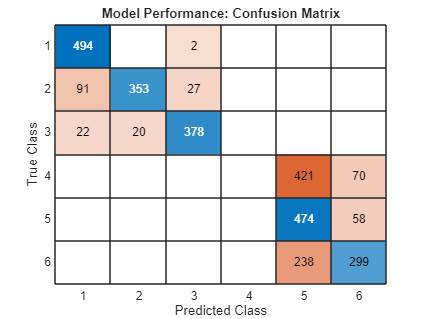

ans = 2


% Confusion Matrix
figure;
confusionchart(YTest, YPred);
title('Model Performance: Confusion Matrix');